# **drawAxes**

Draw coordinate axes.

## Description

## Syntax

drawAxes(form,d1,d2,xc,yc)

drawAxes(form,d1,d2,xc,yc,LineSpec)

p = drawAxes(__)

## Description

## Method

## Arguments

### Input Arguments

**form **- arrowhead type: use 1,2,3,11 for arrow

**d1 **- width of arrowhead 

**d2 **- length of axes

**xc       **-  the center point

**yc       **- 

### **Optional input**

**rot **- axes rotation angle

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with fields

- p.xk, p.yk -- key points 

- p.color - line color

## Examples

### Example 1

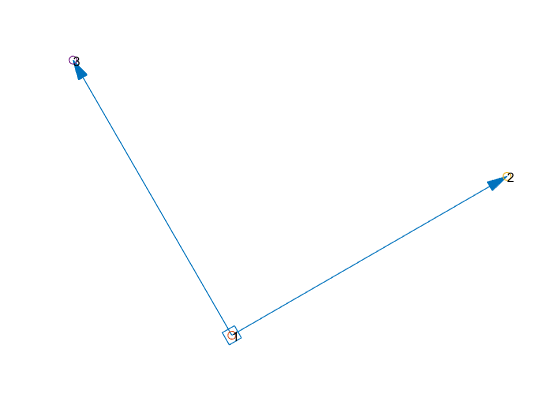

figure
hold on
axis equal
axis off
a = drawAxes( 2, 0.25, 4, 0, 0, 30);
for k = 1:length(a.xk)
    scatter(a.xk(k),a.yk(k))
    text(a.xk(k),a.yk(k),num2str(k))
end
grid on

### **Example 2**

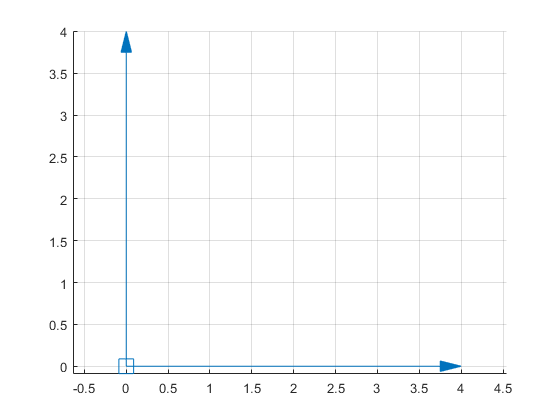

figure
axis equal
hold on
drawAxes( 2, 0.25, 4, 0, 0)

grid on

### **Example 3**

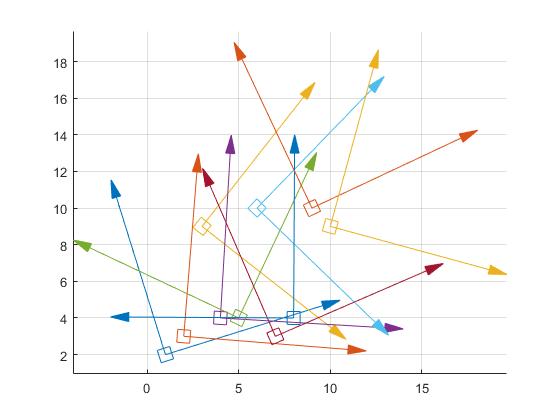

figure
axis equal
hold on
for k = 1:10
    drawAxes( 2, 1, 10,k, randi(10,1,1), 45*randn)
end
grid on

## Example 4

Principal components analysis in two-dimensions

drawInit
np = 1000;
xx = 10*randn(np,1);
yy = randn(np,1);
th = 180*rand(np,1);
x = xx.*cosd(th) - yy.*sind(th);
y = xx.*sind(th) + yy.*cosd(th);
scatter(x,y,20,'.')
p=PCA2d(x,y)

p = struct with fields:
     xm: -0.0758
     ym: -0.3990
     s1: 7.3495
     s2: 6.9394
    th1: 4.9269
    th2: 94.9269
      S: [2×2 double]
      C: [2×2 double]


p.C

ans =     0.9963    0.0859
   -0.0859    0.9963


[coeff]=pca([x,y])

coeff =     0.9963   -0.0859
    0.0859    0.9963


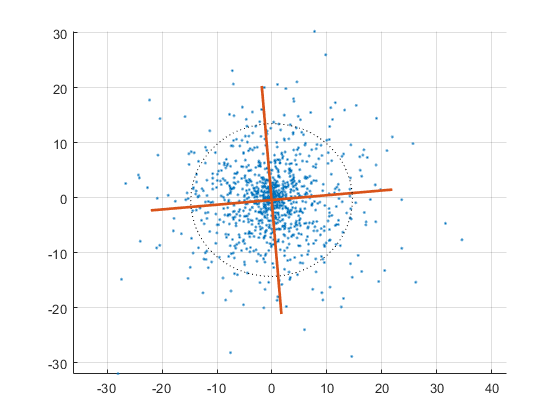

r1=drawCross(3*p.s1,3*p.s2,p.xm,p.ym,p.th1,'LineWidth',2);
drawEllipse(2*p.s1,2*p.s2,p.xm,p.ym,p.th1,'k:')
grid on

## See also

## References